# System Identification - Interpolation

clear all; close all; clc;
addpath('Functions\')

# Interpolation

% Data
D = [0 340 700 1077 1469 1872 2288 2714 3147 3588 4034 4485 4939 5397 5857 6317 6780 7243 7707 8170 8700];
Q = [0 42 85 128 172 214 256 295 332 367 400 431 460 488 515 540 565 588 610 630 651];


% Polynomial curve fitting
n = 3; % Degree of the polynomial
p = polyfit(D,Q,n)

p =     0.0000   -0.0000    0.1314   -1.5273


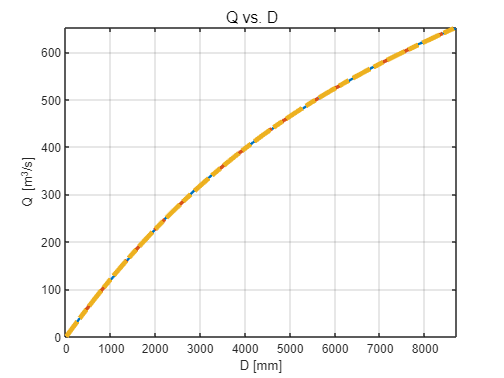

% p(x) = 0.0740 x + 63.8501
% x1 = linspace(0,8700,size(D,2));
time = [1:1:8700];
yi = polyval(p,time);

p_new = [3.12917441263e-10 -9.19281451555e-6 0.13143863318 -1.52730983064];
yi2 = polyval(p_new,time);

% time = [1:1:8700];
% yi = spline(D,Q,time);

% for i=1:size(D,2)
%     y_fit(i) = 201.5501*D(i) + 369.9524;
% end

% Plots
figure;
sgtitle('Q vs. D')
plot(D,Q,'LineWidth',2); hold on;
plot(time,yi,'--','LineWidth',3); hold on;
plot(time,yi2,'-.','LineWidth',4);
xlabel('D [mm]'); ylabel('Q [m^3/s]');
grid; xlim([0 8700]); ylim([0 651]);

num2str(p(1),50)

ans = '3.1291744126309250313504732180023681226144205425044e-10'

num2str(p(2),50)

ans = '-9.1928145155548020544655080099616384359251242130995e-06'

num2str(p(3),50)

ans = '0.13143863318169504705856809323449851945042610168457'

num2str(p(4),50)

ans = '-1.5273098306425236803107736704987473785877227783203'

The formula for the flow out of the gate regarding to the opening D can be expressed as


$$Q(D) = aD^3 + bD^2 + cD + d$$


where


$$a \approx 3.12917441263\cdot 10^{-10} \\
b \approx -9.19281451555 \cdot 10^{-10} \\
c \approx 0.13143863318 \\
d \approx 1.52730983064 $$


# Equation for D - Gate opening

The hydraulic jack that opens and closes the gate can be controlled by, let's say, $u \in [0:1] \%$. $u$ has to be multiplied by $8.7m$ to choose the opening for the gate.The hydraulic jack then controls the gate opening $D$.

Let's find a equation for $D$

u = [0:0.1:1]; 

L_jack_min = 5.786; % [m], hydraulic jack for gate opening
L_jack_max = 12.324; % [m], hydraulic jack for gate opening

D_min = 0;
D_max = 8.700;

% Let's create vectors for the jack and D.
L_vec = [L_jack_min:1:L_jack_max];
step_D = D_max/(size(L_vec,2)-1);
D_vec = [D_min:step_D:D_max];

size(L_vec,2)

ans = 7

size(D_vec,2)

ans = 7

% Polynomial curve fitting
n = 1; % Degree of the polynomial
p_1 = polyfit(D_vec,L_vec,n)

p_1 =     0.6897    5.7860


% p(x) = 0.0740 x + 63.8501
% x1 = linspace(0,8700,size(D,2));
time_1 = [0:8.7/7:8.7];
yi_1 = polyval(p_1,time_1);

% p_new = [3.12917441263e-10 -9.19281451555e-6 0.13143863318 -1.52730983064];
% yi2 = polyval(p_new,time);

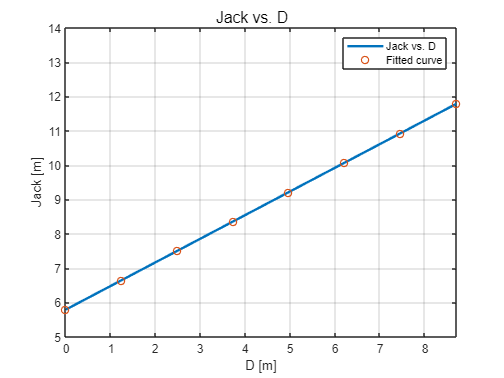

% Plots
figure;
sgtitle('Jack vs. D')
plot(D_vec,L_vec,'LineWidth',2); hold on;
plot(time_1,yi_1,'o','LineWidth',1);
ylabel('Jack [m]'); xlabel('D [m]');
grid; xlim([0 8.7]); ylim([5 14]);
legend('Jack vs. D','Fitted curve')

num2str(p_1(1),50)

ans = '0.68965517241379314938853895000647753477096557617188'

num2str(p_1(2),50)

ans = '5.7860000000000004760636329592671245336532592773438'

The formula to control the gate using $u$ is


$$D(u) = 0.6896551724 (u\cdot 8.7) + 5.786$$


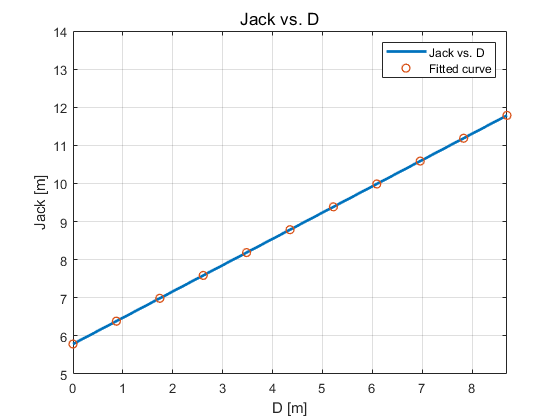

% Let's try it out

D_1 = 0.6896551724*(u*8.7)+5.786;

% Plots
figure;
sgtitle('Jack vs. D')
plot(D_vec,L_vec,'LineWidth',2); hold on;
plot(u*8.7,D_1,'o','LineWidth',1);
ylabel('Jack [m]'); xlabel('D [m]');
grid; xlim([0 8.7]); ylim([5 14]);
legend('Jack vs. D','Fitted curve')

# Trendlína fyrir Cg

Cg_vs_D = load("Cg_vs_D.mat");

Cg_vs_D.ReglunHagalonS1.Cg(1) = 0.7730;
n = 7; % Degree of the polynomial

Cg = Cg_vs_D.ReglunHagalonS1.Cg; 
D  = Cg_vs_D.ReglunHagalonS1.Opnun;

for i=1:length(D)
    test(i) = -5.1854385647666910937633559519621684330559219233692e-07*D(i)^n ...
            + 2.3009388243133869431924706794312385227385675534606e-05*D(i)^(n-1) ...
            - 0.00039326051774348001841691280233703764679376035928726*D(i)^(n-2) ...
            + 0.0032245124407480371502010552120509601081721484661102*D(i)^(n-3) ...
            - 0.012403237757656533982175695030036877142265439033508*D(i)^(n-4) ...
            + 0.01661740981151977464280733443047211039811372756958*D(i)^(n-5) ...
            - 0.012264797555097968484449921788836945779621601104736*D(i)^(n-6) ...
            + 0.77434799435072565465532079542754217982292175292969; 
end

% Polynomial curve fitting

p_1 = polyfit(D,Cg,n)

p_1 =    -0.0000    0.0000   -0.0004    0.0032   -0.0124    0.0166   -0.0123    0.7743


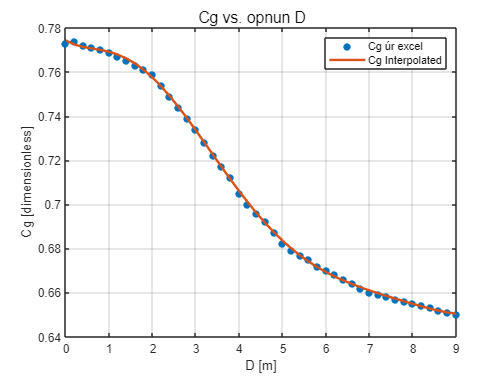

time_1 = (0:(9/(length(Cg)-1)):9);
yi_1 = polyval(p_1,time_1);

% Plots
figure;
sgtitle('Cg vs. opnun D')
plot(D,Cg,'*','LineWidth',2); 
hold on;
% plot(time_1,yi_1,'o','LineWidth',1);
% hold on;
plot(time_1,test,'LineWidth',2);
ylabel('Cg [dimensionless]'); xlabel('D [m]');
grid; 
% xlim([0 8.7]); ylim([5 14]);
legend('Cg úr excel','Cg Interpolated')

num2str(p_1(1),50)

ans = '-5.1854385647666910937633559519621684330559219233692e-07'

num2str(p_1(2),50)

ans = '2.3009388243133869431924706794312385227385675534606e-05'

num2str(p_1(3),50)

ans = '-0.00039326051774348001841691280233703764679376035928726'

num2str(p_1(4),50)

ans = '0.0032245124407480371502010552120509601081721484661102'

num2str(p_1(5),50)

ans = '-0.012403237757656533982175695030036877142265439033508'

num2str(p_1(6),50)

ans = '0.01661740981151977464280733443047211039811372756958'

num2str(p_1(7),50)

ans = '-0.012264797555097968484449921788836945779621601104736'

num2str(p_1(8),50)

ans = '0.77434799435072565465532079542754217982292175292969'

The formula for $C_g$ can be expressed as


$$C_g(D) = -5.185438 \cdot 10^{-7}\,D + 2.3009388 \cdot 10^{-5} \, D- 0.00039326 \, D + 0.0032245 \, D - 0.01240324 \, D +0.0166174 \, D - 0.01226 \, D + 0.7743 \, D + 0.7743$$


# Rennsli inn í lón 2020 - 2021

Rennsli inn í lón frá 26. maí til 3. júní.

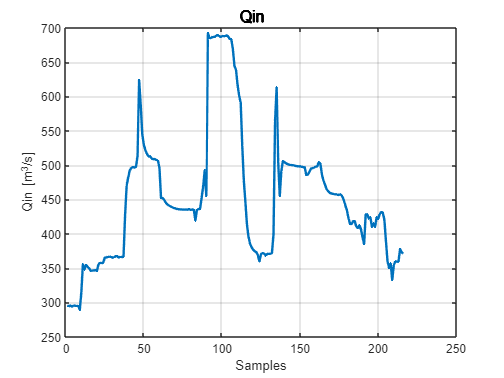

clear all; close all; clc;
Qin_table = load("Qin_2021_1.mat");
Qin_data = cell2mat(struct2cell(Qin_table));
% N = length(Qin_data(:,4));
% time(1:N) = 

% Plots
figure;
sgtitle('Qin')
plot(Qin_data(:,4),'LineWidth',2); 
% hold on;
% plot(time_1,yi_1,'o','LineWidth',1);
% hold on;
% plot(time_1,test,'LineWidth',2);
ylabel('Qin [m^3/s]'); xlabel('Samples');
grid; 

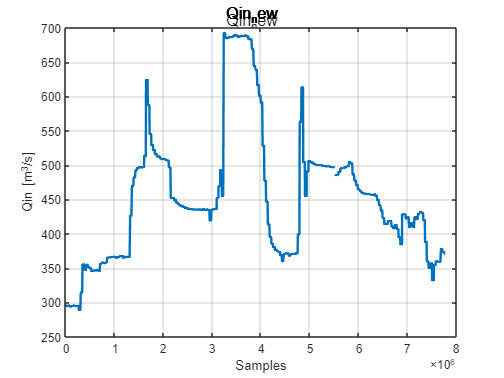

% xlim([0 8.7]); ylim([5 14]);
% legend('Cg úr excel','Cg Interpolated')

time = 60*60*24*9;

Qin = Qin_data(:,4);
n = numel(Qin);

% F = fillmissing(A,'constant',v)
% p_1 = polyfit(D,Cg,n);
Qin_new = interp1(1:n, Qin, linspace(1, n, 7776000), 'nearest');
% time_1 = (0:(9/(length(Cg)-1)):9);

% Plots
figure;
sgtitle('Qin_new')
plot(Qin_new,'LineWidth',2); 
% hold on;
% plot(time_1,yi_1,'o','LineWidth',1);
% hold on;
% plot(time_1,test,'LineWidth',2);
ylabel('Qin [m^3/s]'); xlabel('Samples');
grid; 

% xlim([0 8.7]); ylim([5 14]);
% legend('Cg úr excel','Cg Interpolated')


TF = isnan(Qin_new);
any(TF, 'all') % Check if there is a NaN in the dataset

ans = logical
   0


save('Qin_new.mat','Qin_new');

# Trendlína fyrir seiðafleytu


% Cg_vs_D = load("Cg_vs_D.mat");

% Cg_vs_D.ReglunHagalonS1.Cg(1) = 0.7730;
n_Sei = 11; % Degree of the polynomial

Cp = [0.7810 0.775 0.769 0.764 0.745 0.72 0.69 0.665 0.64 0.615 0.59 0.565]; 
D_Sei  = [0 0.3 0.4 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5];

for i=1:length(D_Sei)
    test_Sei(i) = 3.9371504004013375933260926453627348564623389393091e-05*D_Sei(i)^n_Sei ...
            - 0.00078311582752380601638031443201271031284704804420471*D_Sei(i)^(n_Sei-1) ...
            + 0.0065634009166082784778040171147495129844173789024353*D_Sei(i)^(n_Sei-2) ...
            - 0.030548285458790454954813853305495285894721746444702*D_Sei(i)^(n_Sei-3) ...
            + 0.089085328861756823970452501271211076527833938598633*D_Sei(i)^(n_Sei-4) ...
            - 0.17915179662559704842905716759560164064168930053711*D_Sei(i)^(n_Sei-5) ...
            + 0.26863116322472624375450322986580431461334228515625*D_Sei(i)^(n_Sei-6) ...
            - 0.28694958739425385774168830721464473754167556762695*D_Sei(i)^(n_Sei-7) ...
            + 0.15542890162568401279941099346615374088287353515625*D_Sei(i)^(n_Sei-8) ...
            + 0.020083094415124562448493605870680767111480236053467*D_Sei(i)^(n_Sei-9) ...
            - 0.097398475242998286405260444098530570045113563537598*D_Sei(i)^(n_Sei-10) ...
            + 0.80000000000126003651956807516398839652538299560547; 
end

% for i=1:length(D_Sei)
%     test_Sei(i) = 0.7810*D_Sei(i)^n_Sei ...
%             + 0.7685*D_Sei(i)^(n_Sei-1) ...
%             + 0.7520*D_Sei(i)^(n_Sei-2) ...
%             + 0.7347*D_Sei(i)^(n_Sei-3) ...
%             + 0.7119*D_Sei(i)^(n_Sei-4) ...
%             + 0.6874*D_Sei(i)^(n_Sei-5) ...
%             + 0.6670*D_Sei(i)^(n_Sei-6) ...
%             + 0.6477*D_Sei(i)^(n_Sei-7) ...
%             + 0.6243*D_Sei(i)^(n_Sei-8) ...
%             + 0.6107*D_Sei(i)^(n_Sei-9) ...
%             + 0.5745*D_Sei(i)^(n_Sei-10) ...
%             + 0.5650; 
% end

% Polynomial curve fitting

p_1_Sei = polyfit(D_Sei,Cp,n_Sei)

p_1_Sei =     0.0003   -0.0060    0.0587   -0.3291    1.1631   -2.7094    4.2169   -4.3275    2.7871   -1.0109    0.1209    0.7810


time_1_Sei = (0:(4.5/(length(Cp)-1)):4.5);
yi_1_Sei = polyval(p_1_Sei,time_1_Sei)

yi_1_Sei =     0.7810    0.7685    0.7520    0.7347    0.7119    0.6874    0.6670    0.6477    0.6243    0.6107    0.5745    0.5650


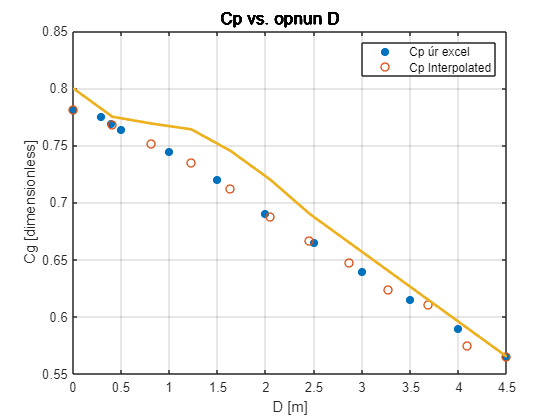


% Plots
figure;
sgtitle('Cp vs. opnun D')
plot(D_Sei,Cp,'*','LineWidth',2); 
hold on;
plot(time_1_Sei,yi_1_Sei,'o','LineWidth',1);
hold on;
plot(time_1_Sei,test_Sei,'LineWidth',2);
ylabel('Cg [dimensionless]'); xlabel('D [m]');
grid; 
% xlim([0 8.7]); ylim([5 14]);
legend('Cp úr excel','Cp Interpolated')

num2str(p_1_Sei(1),50)

ans = '0.00026276950494958745086979123861681273410795256495476'

num2str(p_1_Sei(2),50)

ans = '-0.0059659494494911802925374288975035597104579210281372'

num2str(p_1_Sei(3),50)

ans = '0.058697792397962467170202671695733442902565002441406'

num2str(p_1_Sei(4),50)

ans = '-0.32905269432901118609180457497132010757923126220703'

num2str(p_1_Sei(5),50)

ans = '1.1630795958701389825051819570944644510746002197266'

num2str(p_1_Sei(6),50)

ans = '-2.709435744765158915470237843692302703857421875'

num2str(p_1_Sei(7),50)

ans = '4.2168628540366350776480430795345455408096313476562'

num2str(p_1_Sei(8),50)

ans = '-4.3275352685382681983128350111655890941619873046875'

num2str(p_1_Sei(9),50)

ans = '2.7870943534366818816749855614034458994865417480469'

num2str(p_1_Sei(10),50)

ans = '-1.0109433597528032500179051567101851105690002441406'

num2str(p_1_Sei(11),50)

ans = '0.12093565157401543752602179893074207939207553863525'

num2str(p_1_Sei(12),50)

ans = '0.78100000001435210261746533433324657380580902099609'